# Spline Based Estimators

clear
load('dgp.mat')
[n,k]= size(X);
n_knots = 9; %internal

step = floor(n/n_knots);
offset = floor((n-step*(n_knots-1))/2)+1;
indecies = [1 offset:step:n-1 n];
knots = X(indecies);

lambda = 0.05;
order =4;

## Regression Cubic Spline

$1,x,x^2,...,x^p,(x-x_1)_+^p,...,(x-x_k)_+^p$  basis functions for knots $x_1,...,x_k$, and p=order-1

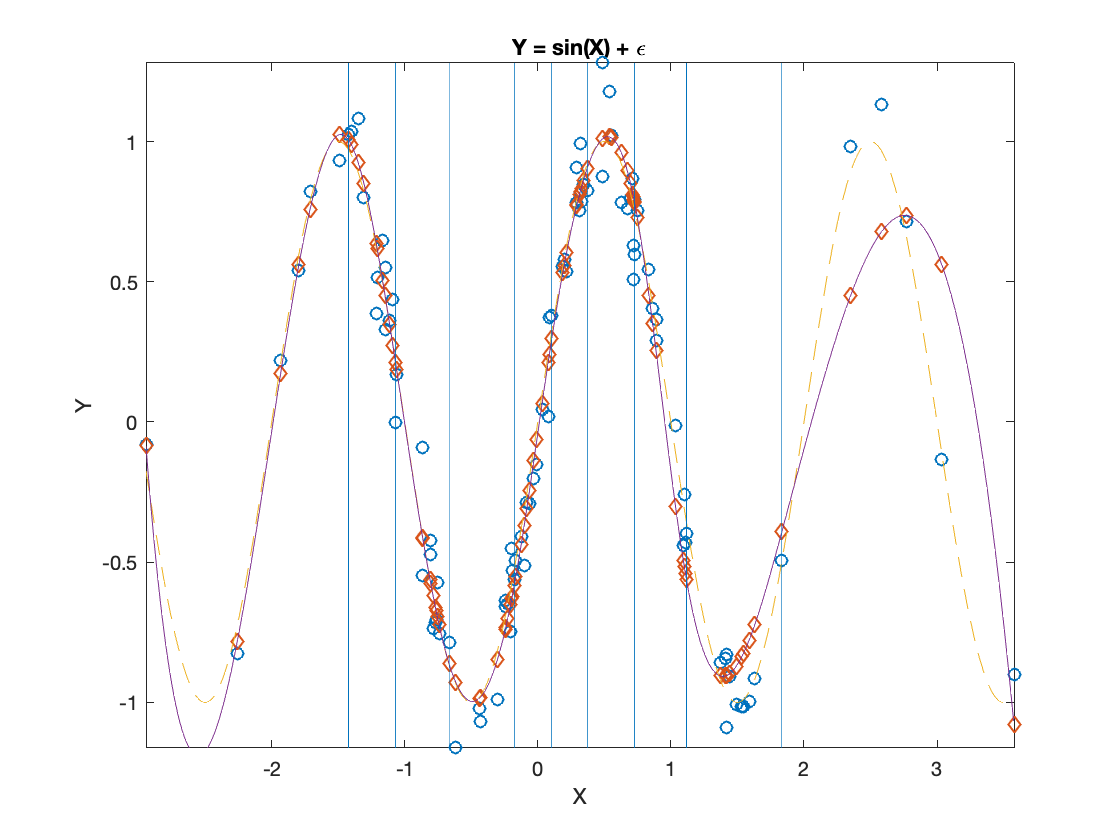

G = zeros(n,order+n_knots);
for i = 1:order
    G(:,i) = X.^(i-1);
end

for j = 1:n_knots
    G(:,order+j) = subplus(X-knots(j+1)).^(order-1);
end

RS = G*(G'*G)^-1*G';
Y_RS = RS*Y;
beta = (G'*G)^-1*G'*Y;

%for plotting the spline curve
xx = X(1):0.01:X(n);
p = fliplr(beta(1:order)');
yy = polyval(p,xx);
for l = 2:n_knots+1
    pp = mkpp([knots(l) X(n)],[beta(l+order-1) 0 0 0]);
    yy = yy + ppval(pp,xx).*(xx-knots(l)>0);
end

y_limits = [min(min(Y),min(Y_RS)) max(max(Y),max(Y_RS))];
plot(X,Y,'o',X,Y_RS,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-')
title('Y = sin(X) + \epsilon');
%legend('Observed','Estimated', 'Truth','Spline Regression','Location','Best');
xlabel('X');
ylabel('Y');
xlim([X(1) X(n)]);
ylim(y_limits);
for i=2:n_knots+1
    line([knots(i) knots(i)], y_limits); 
end
hold off;


rs_df1 = trace(RS)

rs_df1 = 13.0000

rs_df2 = n-trace(2*RS -RS*RS')

rs_df2 = 87.0000

rs_df3 = trace(RS*RS')

rs_df3 = 13.0000

rs_df4 = trace(eye(size(RS))-RS)

rs_df4 = 87.0000

cond_RS = norm(RS)*norm(RS^-1)

cond_RS = 5.7543e+18

## Smoothing Cubic Spline

beta that minimizes the following, $1,x,x^2,...,x^p,(x-x_1)_+^p,...,(x-x_k)_+^p$  basis functions for knots $x_1,...,x_k$, and p=order-1


$$||y-G\beta||_2^2 + \lambda\beta^T\Omega\beta \text{, where } G_{ij} = g_j(x_i) \text{ and } \Omega_{jk} = \int g''_j(t)g''_k(t)dt \enspace i,j = 1,...,n$$



$$\hat{\beta} = (G^TG+\lambda\Omega)^{-1}G^Ty$$


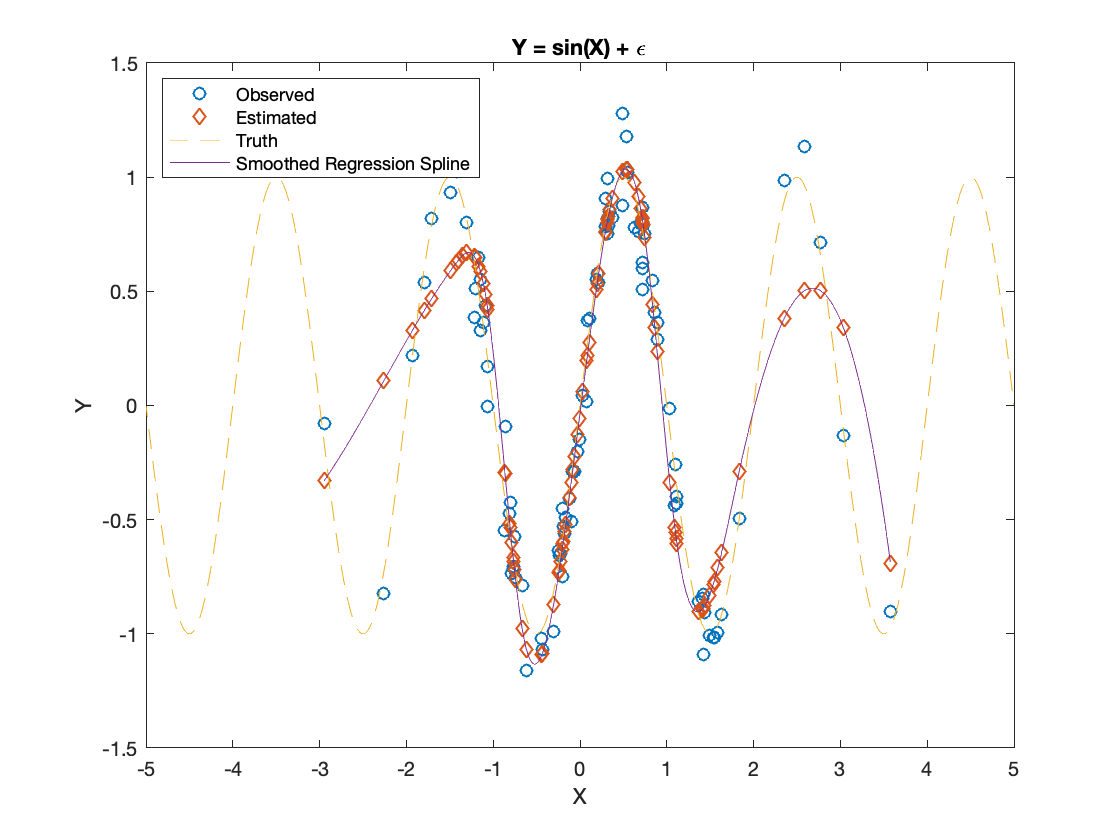

G = zeros(n,order+n_knots);
for i = 1:order
    G(:,i) = X.^(i-1);  
end
for j = 1:n_knots
    x_l = knots(j+1);
    G(:,order+j) = subplus(X-x_l).^(order-1);
end

basisPoly = [flipud(eye(4)); ones(n_knots,1) ...
    -3*knots(2:end-1) 3*knots(2:end-1).^2 ...
    -knots(2:end-1).^3];

g2Prime = zeros(order+n_knots,order-2);

for k = 1:n_knots+order
    deriv2 = polyder(polyder(basisPoly(k,:)));
    g2Prime(k,:)=[zeros(1,order-2-size(deriv2,2)) deriv2];
end

tempKnots = [repmat(knots(1),order-1,1); knots];
omega = zeros(order+n_knots,order+n_knots);
for l = 1:n_knots+order
    for m= 1:n_knots+order
        p = polyint(conv(g2Prime(l,:),g2Prime(m,:)));
        omega(l,m) = polyval(p,X(end))-polyval(p,X(1))*...
            (tempKnots(l)==X(1))*(tempKnots(m)==X(1));
    end
end

S = G*(G'*G+lambda*omega)^-1*G';
Y_S = S*Y;
beta = (G'*G+lambda*omega)^-1*G'*Y;

%for plotting the spline curve
xx = X(1):0.01:X(n);
p = fliplr(beta(1:order)');
yy = polyval(p,xx);

for l = 2:n_knots+1
    pp = mkpp([knots(l) X(n)],[beta(l+order-1) 0 0 0]);
    yy = yy + ppval(pp,xx).*(xx-knots(l)>0);
end

plot(X,Y,'o',X,Y_S,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,yy,'-');
title('Y = sin(X) + \epsilon');
legend('Observed','Estimated', 'Truth','Smoothed Regression Spline','Location','Northwest');
xlabel('X');
ylabel('Y');
%xlim(domain);
%ylim(range);
hold off;


s_df1 = trace(S)

s_df1 = 10.6344

s_df2 = n-trace(2*S -S*S')

s_df2 = 88.9409

s_df3 = trace(S*S')

s_df3 = 10.2097

s_df4 = trace(eye(size(S))-S)

s_df4 = 89.3656

cond_S = norm(S)*norm(S^-1)

cond_S = 2.5918e+19

cond_S_inner = 2.2592e+19

2 things need to take into account:

condition number very dependent on h and number of knots

also perhaps on functions use to calculate functions for estimator

spline: knots and some other parameter

series estimator

choice of h, knots, etc

non-stochastic choice of h,k (not data dependent) tensor product-ish

and/or

stochastic choices, (data driven)

- still need theory that relates condition number to smoothness imparting on estimation of regressors!!!

leverage in linear models 

## Specification help

Splines: [http://www.stat.cmu.edu/~larry/=sml/nonpar.pdf](http://www.stat.cmu.edu/~larry/=sml/nonpar.pdf) and [http://cda.psych.uiuc.edu/matlab_pdf/splines.pdf](http://cda.psych.uiuc.edu/matlab_pdf/splines.pdf)

## Functions

function pp = bSpline(x,center)
% makes a cubic B-spline from x(center-2) to x(center+2)
% with breaks over all x (will do knots later)
n = length(x);
if center>n-2 | center<3
    error('Must have at least 5 points for cubic B-spline')
end
temp = fn2fm(bspline(x(center-2:center+2)),'pp');
leadZeros = center-3;
trailZeros = n-center-2;

coefs = [zeros(leadZeros,4); temp.coefs; zeros(trailZeros,4)];
pp = mkpp(x,coefs);
end